# ThreeLink URDF and waypoint tracking

## **prerequisites:**

- Familiar with basics of kinematics and Matlab

- Reference reading: Chapter 2&3 of Robotics Modelling, Planning and Control  by Bruno Siciliano, Lorenzo Sciavicco, Luigi Villani, and Giuseppe Oriolo  

## Objectives:

- Performs inverse kinematics of a robot manipulator to follow a desired set of waypoints using Matlab Robotics System Toolbox

clear all;
clc;

## Load and display robot

robot = importrobot('planar_three_link.urdf');
% Add gravity
robot.Gravity = [0 0 -9.80665];

axes = show(robot);
axes.CameraPositionMode = 'auto';
set(gcf,'Visible','on');



## Create a set of desired waypoints

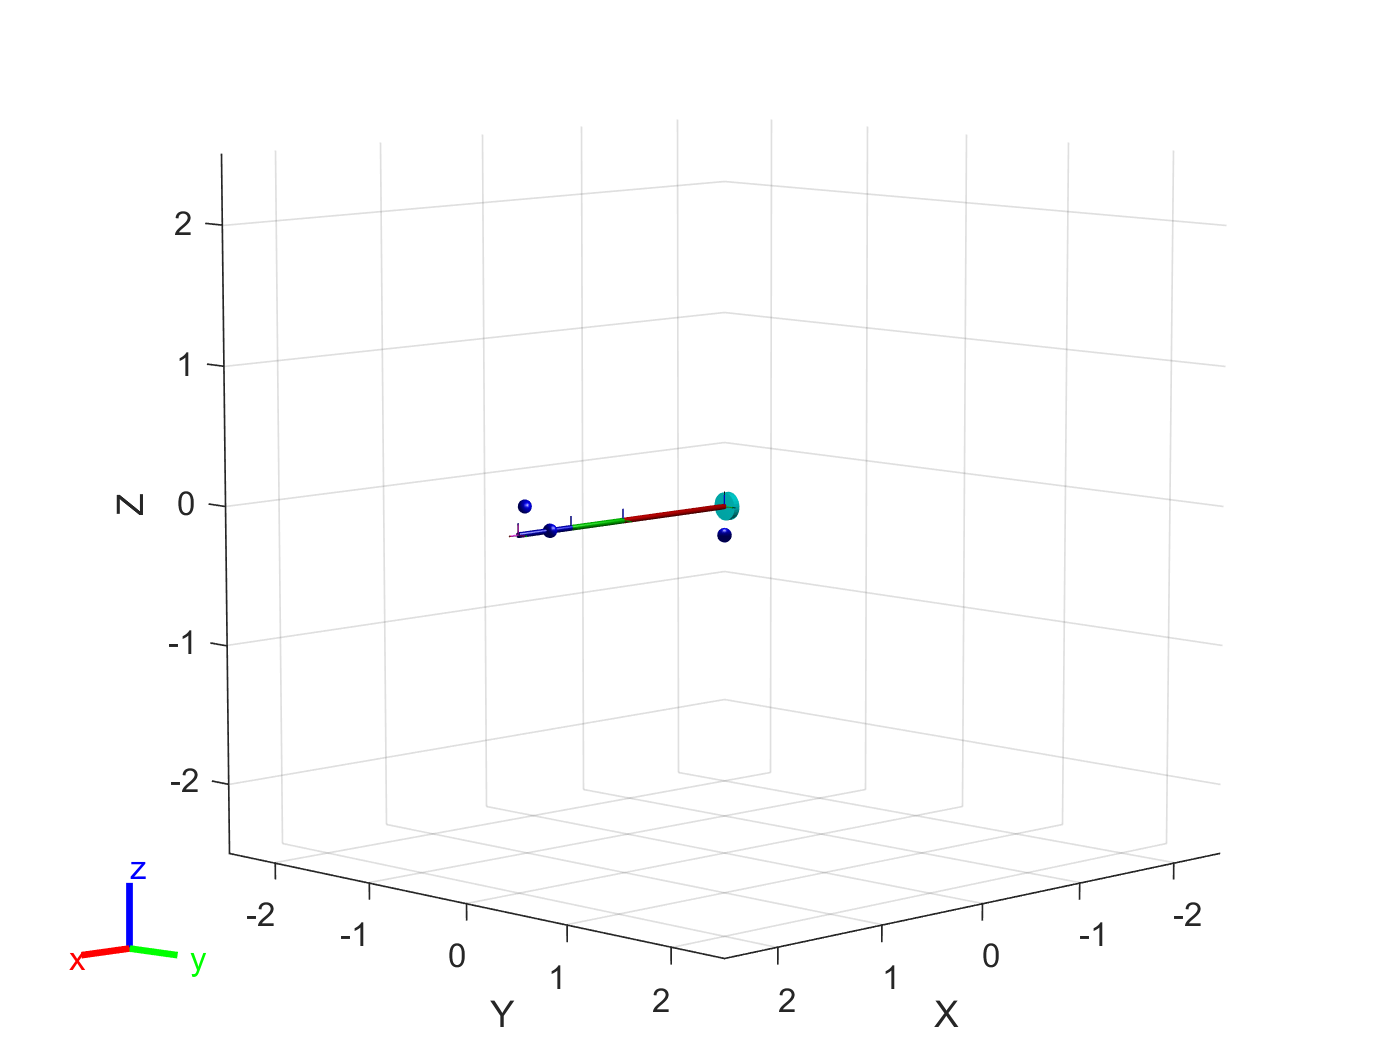

wayPoints = [1 -1 0.0;1.7 0 0.0; 1 1 0.0]; % Alternate set of wayPoints
wayPointVels = [0.0 0.0 0;0.0 0.5 0;0.0 0.0 0];

% plot the waypoints as blue spheres
for idx = 1:size(wayPoints,1)
   plotSpheres(0.05,wayPoints(idx,:));
end

## Create a smooth trajectory from the waypoints

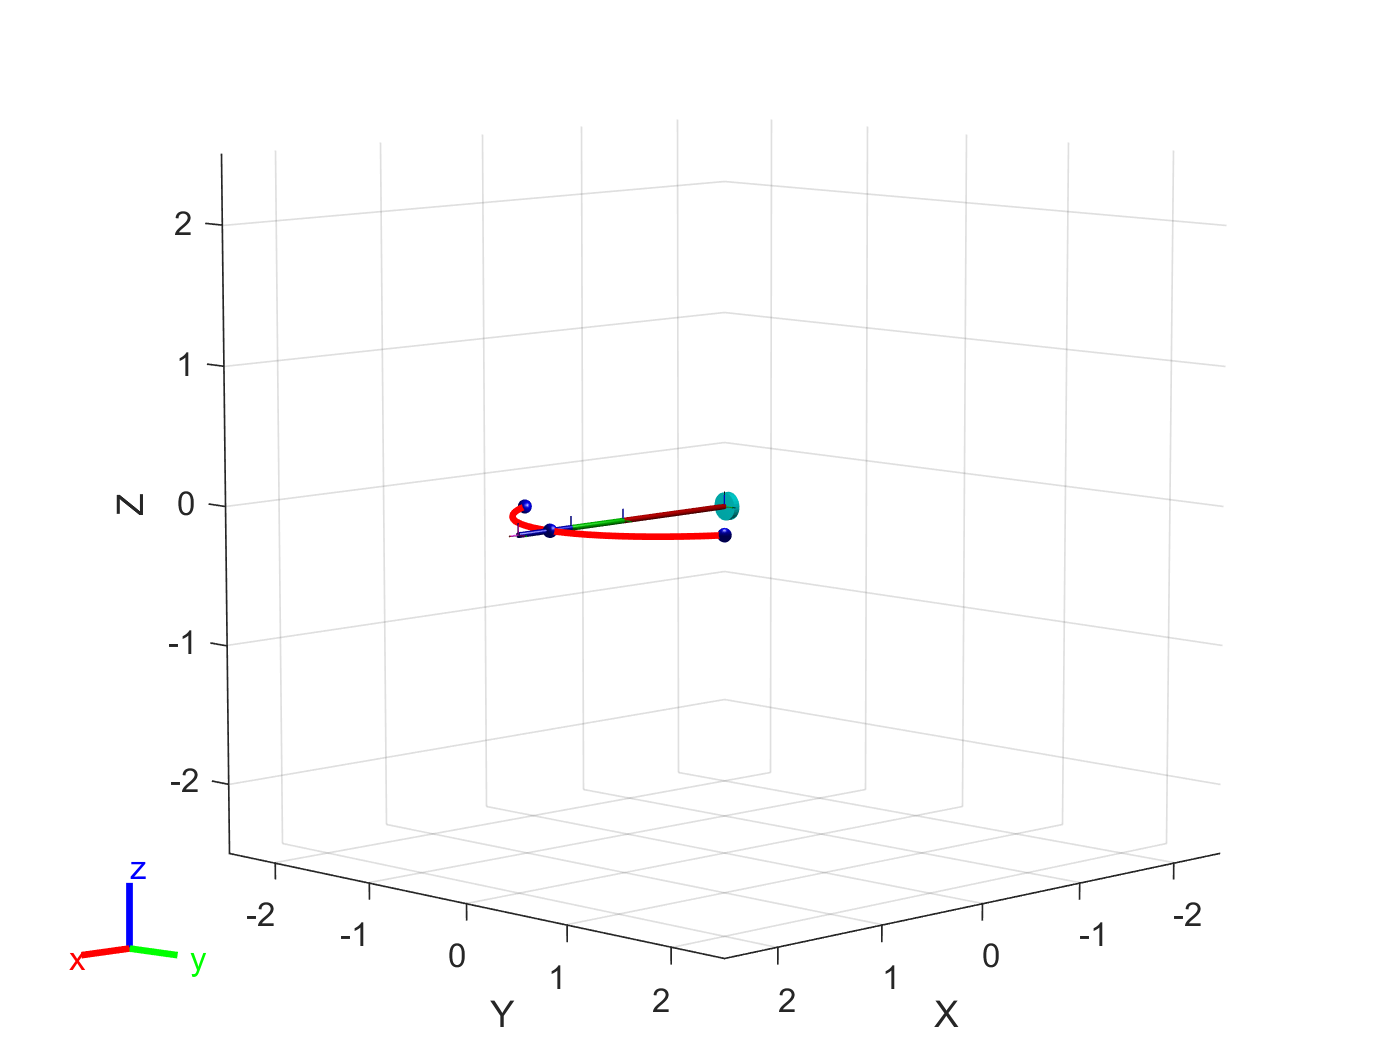

numTotalPoints = size(wayPoints,1)*10;
waypointTime = 4;
trajType = 'cubic'; %'trapezoidal'; 
switch trajType
    case 'trapezoidal'
        trajectory = trapveltraj(wayPoints',numTotalPoints,'EndTime',waypointTime);
    case 'cubic'
        wpTimes = (0:size(wayPoints,1)-1)*waypointTime;
        trajTimes = linspace(0,wpTimes(end),numTotalPoints);
        trajectory = cubicpolytraj(wayPoints',wpTimes,trajTimes, ...
                     'VelocityBoundaryCondition',wayPointVels');
end
% Plot trajectory spline and waypoints
hold on
plot3(trajectory(1,:),trajectory(2,:),trajectory(3,:),'r-','LineWidth',2);

## Perform Inverse Kinematics

Use desired weights for the solution (First three are orientation, last three are translation). 

Since it is a 2-DOF robot with revolute joints in Z, we do not put a weight on Z rotation; otherwise it limits the solution space

ik = robotics.InverseKinematics('RigidBodyTree',robot);
weights = [0.1 0.1 0 1 1 1];
initialguess = robot.homeConfiguration;

% Call inverse kinematics solver for every end-effector position using the
% previous configuration as initial guess
for idx = 1:size(trajectory,2)
    tform = trvec2tform(trajectory(:,idx)');
    [soln,info] = ik('end_effector',tform,weights,initialguess);
    configSoln(idx,:) = soln;
    solInfo(idx,:) = info;
    if ~strcmp(info.Status,'success')
        disp(info)
    end
    initialguess = configSoln(idx,:);
end

## Visualize robot configurations

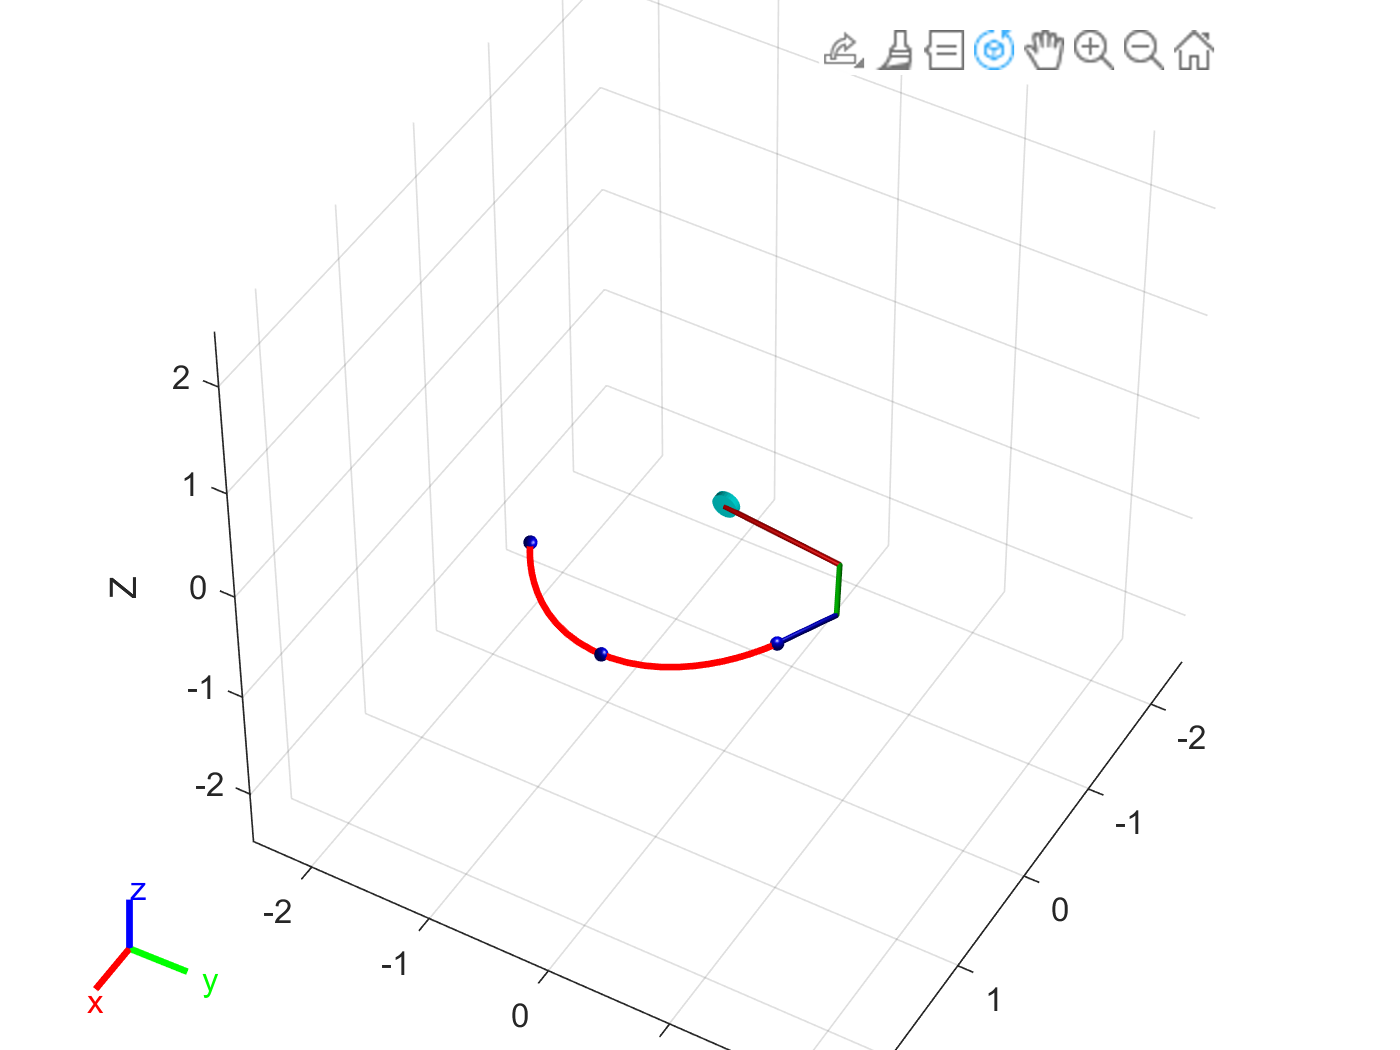

title('Robot waypoint tracking visualization')
%axis([-0.1 0.4 -0.35 0.35 0 0.35]);
for idx = 1:size(trajectory,2)
    show(robot,configSoln(idx,:), 'PreservePlot', false,'Frames','off');
    pause(0.1)
end
hold off

# References

`Bradley Horton : 01-Aug-2016, bradley.horton@mathworks.com.au`

[Teaching Rigid Body Dynamics – a combination of symbolic and numeric computing Video - MATLAB (mathworks.com)](https://www.mathworks.com/videos/teaching-rigid-body-dynamics-a-combination-of-symbolic-and-numeric-computing-1506004876316.html?s_tid=srchtitle_Teaching%20Rigid%20Body%20Dynamics_1)